# Trying to generate PSRN and SAM

12/1/2022

## Generate table

disp_name = ["NEC"; "HP"; "Rift"];

load('compare_RGB_primaries_result_nec')
psnr_rgb_nec = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_nec = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

load('compare_RGB_primaries_result_hp')
psnr_rgb_hp = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_hp = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

load('compare_RGB_primaries_result_rift')
psnr_rgb_rift = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_rift = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

psnr_t = [psnr_rgb_nec; psnr_rgb_hp; psnr_rgb_rift];
psnr_table = array2table(psnr_t,'VariableNames',{'R','G','B'},'RowName',{'NEC','HP','Rift'});
psnr_table

psnr_table = 3×3 table
              R         G         B   
            ______    ______    ______

    NEC     84.218    91.583    98.707
    HP      84.235    86.958    95.938
    Rift     88.76     93.34    95.798


Matlab2latex.table2latex(psnr_table)

sam_t = [sam_rgb_nec; sam_rgb_hp; sam_rgb_rift];
sam_t = rad2deg(sam_t);
sam_table = array2table(sam_t,'VariableNames',{'R','G','B'},'RowName',{'NEC','HP','Rift'});

sam_table

sam_table = 3×3 table
              R         G         B   
            ______    ______    ______

    NEC     2.2257    2.9987    2.3645
    HP      4.8175    3.4332    2.0135
    Rift    3.7291    2.3325    1.9986


Matlab2latex.table2latex(sam_table)

save('psnr_sam_table','psnr_table','sam_table')

## Generate plots

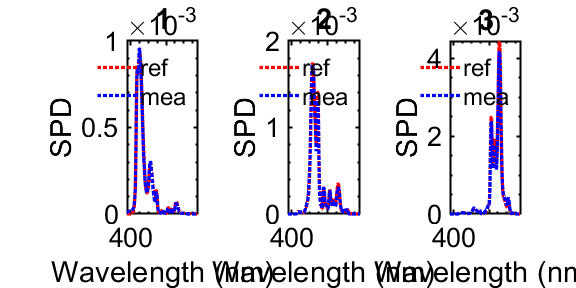

clf; analyze_one_display('compare_RGB_primaries_result_nec','NEC');
set(gcf,'Visible','on')


%clf; analyze_one_display('compare_RGB_primaries_result_hp','HP')
%clf; analyze_one_display('compare_RGB_primaries_result_rift','RIFT')



function analyze_one_display (fn_mat, dispname)
load(fn_mat)

clf

hfig = figure;

set(hfig, 'Units', 'inches', ...
    'Color', [1,1,1]);

set(hfig, ...
    'Units'              , 'inches',...
    'Position'           , [1 1 6 3]);

my_compare_psnr_sam(s_predicted_b,mea_b,1);
my_compare_psnr_sam(s_predicted_g,mea_g,2);
my_compare_psnr_sam(s_predicted_r,mea_r,3);

end


## PSRN and SAM

%
%
%
function [psnr_val sam_deg] = my_compare_psnr_sam (speC1, speC2, no)

s1 = speC1.amplitude;
s2 = speC2.amplitude;
psnr_val = psnr(s1,s2);
sam_deg = rad2deg(sam(s1,s2));

s1 = speC1.amplitude;
s2 = speC2.amplitude;

haxis = subplot(1,3,no);

hold on
plot(380:780,s1,'r:')
plot(380:780,s2,'b:')
%axis([380 780 0 5e-3])
tstr = sprintf('%.2f, %.2f',psnr_val,sam_deg);
title(no)
xlabel('Wavelength (nm)')
ylabel('SPD')
legend('ref','mea')

PlotBeautify(haxis);

end

